radius = 500;

theta = linspace(0, 2*pi, 1000);

x = radius * cos(theta);
y = radius * sin(theta);

point1 = [-1000, 0];
point2 = [3500, 0];

planeA_point = zeros(91, 2);

planeA_point(1:17,:) = [linspace(-1000, -250, 17)', linspace(0, 433, 17)'];

theta = atan2(443, -250);
thetas = linspace(theta, 1.4846, 7);

planeA_point(17:23,:) = 500*[cos(thetas)', sin(thetas)'];

tangentPoints = findTangentPoints(0, 0, 500, 3500, 0);
planeA_point(23:91,:) = [linspace(71.4286, 3500, 69)', linspace(494.8717, 0, 69)'];

planeB_point = [planeA_point(end:-1:1,1), -planeA_point(end:-1:1, 2)]

planeB_point = 1.0e+03 *

    3.5000         0
    3.4496   -0.0073
    3.3992   -0.0146
    3.3487   -0.0218
    3.2983   -0.0291
    3.2479   -0.0364
    3.1975   -0.0437
    3.1471   -0.0509
    3.0966   -0.0582
    3.0462   -0.0655


tangent_A = zeros(68,2,2);
for i=23:91
    tangent_A(i-22,:,:) = findTangentPoints(0, 0, 500, planeA_point(i,1), planeA_point(i,2));
end
atan_A = zeros(1,91);
atan_A(1:16) = 0.5236;
atan_A(17:22) = atan2(-planeA_point(17:22,1), planeA_point(17:22,2));
atan_A(23:91) = atan2(planeA_point(23:91,2)-tangent_A(:,1,2), planeA_point(23:91,1)-tangent_A(:,1,1))-pi;

tangent_B = zeros(68,2,2);
for i=1:68
    tangent_B(i,:,:) = findTangentPoints(0, 0, 500, planeB_point(i,1), planeB_point(i,2));
end
atan_B = zeros(1,91);
atan_B(75:91) = -0.5236-pi;
atan_B(69:74) = atan2(planeB_point(69:74,1), -planeB_point(69:74,2))-pi;
atan_B(1:68) = atan2(planeB_point(1:68,2)-tangent_B(:,2,2), planeB_point(1:68,1)-tangent_B(:,2,1))

atan_B =    -0.1433   -0.1476   -0.1519   -0.1564   -0.1610   -0.1658   -0.1707   -0.1757   -0.1809   -0.1863   -0.1919   -0.1977   -0.2037   -0.2098   -0.2162   -0.2229   -0.2298   -0.2369   -0.2443   -0.2520   -0.2600   -0.2684   -0.2771   -0.2861   -0.2956   -0.3055   -0.3158   -0.3266   -0.3379   -0.3497   -0.3622   -0.3752   -0.3890   -0.4035   -0.4187   -0.4348   -0.4519   -0.4699   -0.4890   -0.5093   -0.5310   -0.5540   -0.5786   -0.6049   -0.6331   -0.6633   -0.6959   -0.7311   -0.7691   -0.8103


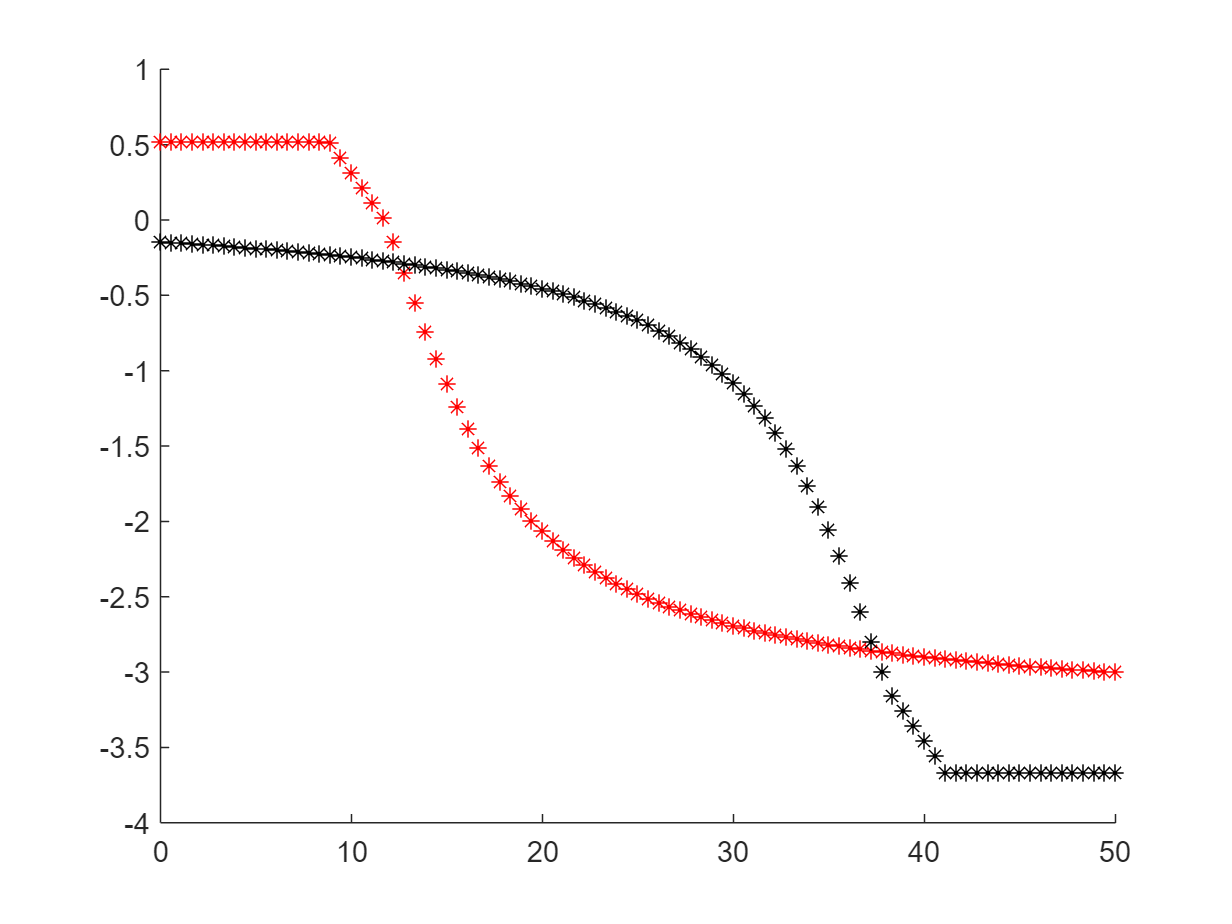

clf
figure;
hold on;

X = linspace(0, 50, 91);
plot(X,atan_A,'*r', X,atan_B,'*k')

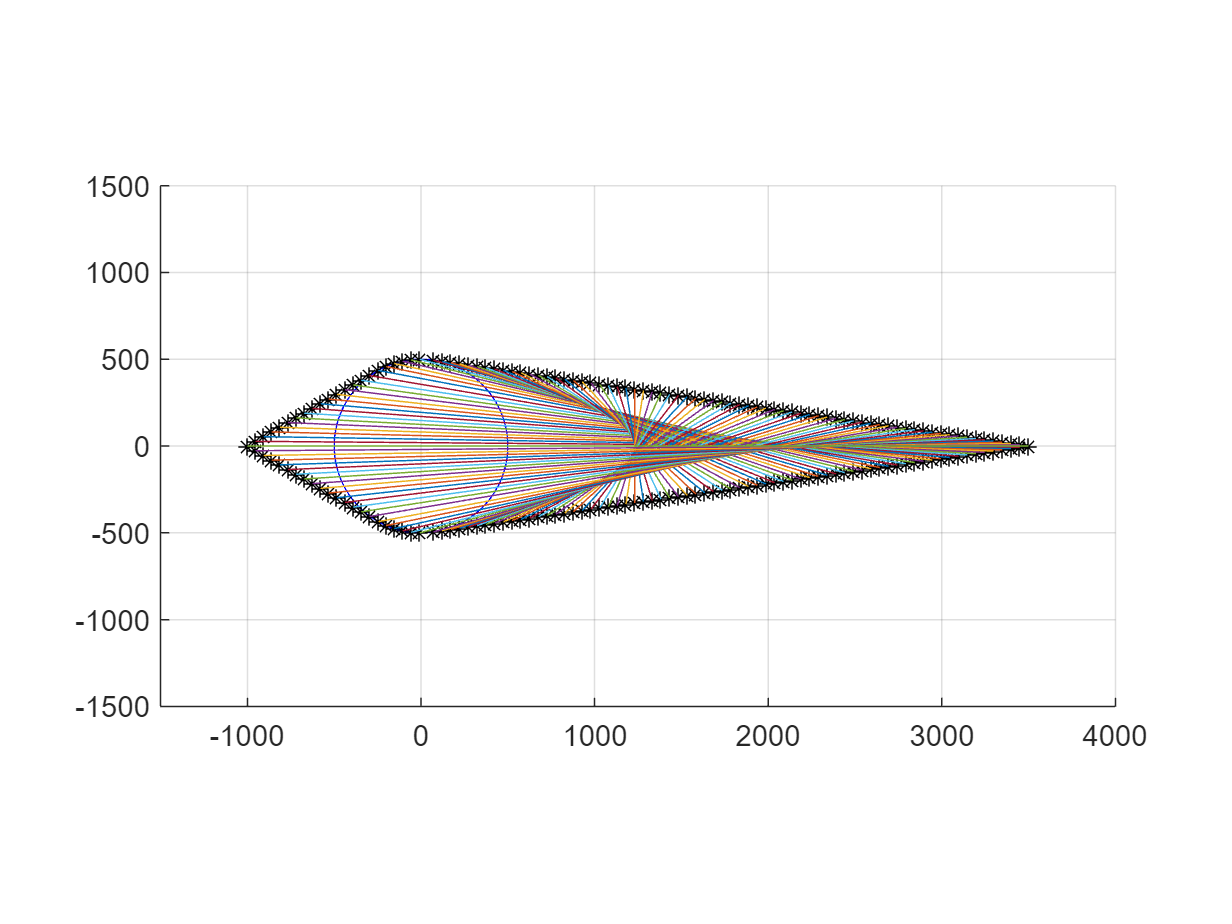

clf
figure;
hold on;

plot(x, y, 'b');

plot(point1(1), point1(2), '*r');
plot(point2(1), point2(2), '*r');

plot(planeA_point(:,1), planeA_point(:,2), '*k')
plot(planeB_point(:,1), planeB_point(:,2), '*k')

for i=1:91
    plot([planeA_point(i,1),planeB_point(i,1)], [planeA_point(i,2), planeB_point(i,2)])
end

axis equal;

xlim([-1500 4000]);
ylim([-1500 1500]);

grid on;